## Set parameters

In this script we will demonstrate multiple scattering of an incident plane wave with direction $(1,0)$ and wavelength $\lambda$ by two circular scatterers with radius $\rho$ and centres at $\mathbf{x}_1$ and $\mathbf{x}_2$. In this script we apply the sound-soft boundary condition on the boundary of the scatterers.

First we will setup the parameters $\lambda$, $\mathbf{x}_1$, $\mathbf{x}_2$ and $\rho$ that determine the scattering problem.

lambda = 2;

x1 = 3i;
x2 = -3i;

rho = 1;

Note: in the code we will represent vectors $(x,y)$ by complex numbers $x + yi$.

## Visualisation of the problem

We will start with a quick plot to visualise the scattering problem.

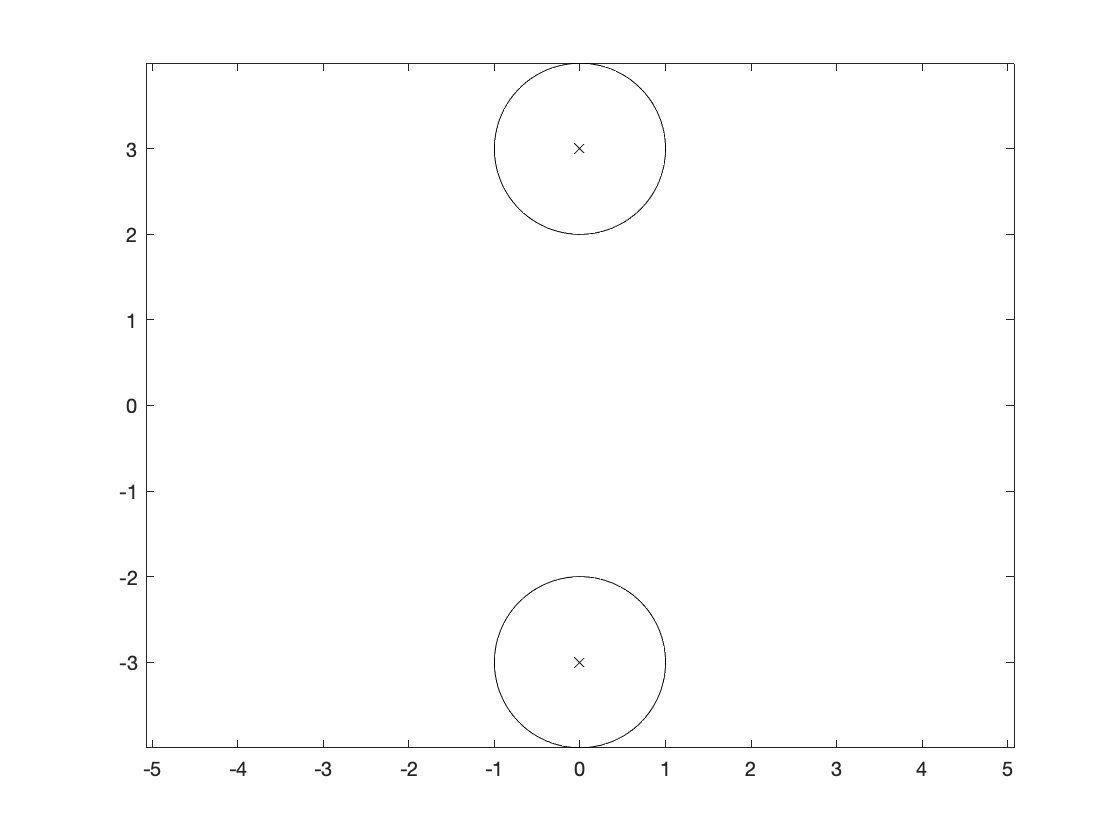

tp = linspace(0,2*pi);
plot(real(x1),imag(x1),'kx',...
    real(x2),imag(x2),'kx',...
    real(x1) + rho*cos(tp),imag(x1) + rho*sin(tp),'k-',...
    real(x2) + rho*cos(tp),imag(x2) + rho*sin(tp),'k-');
axis equal

## Set dependent parameters

Set the wavenumber based on the incident wavelength

        $k = \frac{2 \pi}{\lambda}$.

kwave = 2*pi/lambda;

This is also a good time to setup the incident wave $u^{inc}(\mathbf{x}) = e^{i k \mathbf{x} \cdot (1,0)}$ with direction $(\cos 0,\sin 0)$:

uinc = plane_wave(0,kwave);

## Setup T-matrices

To simulate scattering we will use T-matrices with order $n$ chosen by Wiscombe's formula

        $n \approx  x + 4x^{1/3} + 1$,

where $x = k\rho$ and $\rho$ is the scatterer radius.

n = suggestedorder(kwave,rho);

Because, the scatterers are circular, their T-matrices $T_1$ and $T_2$ are known analytically and there are special TMATROM functions to set them up. The T-matrices are actually the same but they have different origins $\mathbf{x}_1$ and $\mathbf{x}_2$.

T1 = mie_tmatrix(kwave,rho,n,'SOFT',x1);
T2 = mie_tmatrix(kwave,rho,n,'SOFT',x2);

## Multiple scattering simulation

We will represent the incident field by regular wavefunction expansions 

        $u^{inc}(\mathbf{x}) = \sum_{|l| \leq n} a^{(1)}_l J_{|l|}(kr_1) e^{il \theta_1}$,

        $u^{inc}(\mathbf{x}) = \sum_{|l| \leq n} a^{(2)}_l J_{|l|}(kr_2) e^{il \theta_2}$,

of the incident wave with local origins $\mathbf{x}_1$ and $\mathbf{x}_2$. Here $(r_1,\theta_1)$ and $(r_2,\theta_2)$ are polar coordinates for $\mathbf{x}$ with respect to the origins $\mathbf{x}_1$ and $\mathbf{x}_2$ respectively. We will represent the scattered field as

        
$$u(\mathbf{x}) = u_1(\mathbf{x}) + u_2(\mathbf{x})$$


where

        $u_1(\mathbf{x}) = \sum_{|l| \leq n} b^{(1)}_l H^{(1)}_{|l|}(kr_1) e^{il \theta_1}$,

        $u_2(\mathbf{x}) = \sum_{|l| \leq n} b^{(2)}_l H^{(1)}_{|l|}(kr_2) e^{il \theta_2}$.

The field incident on the first scatterer comprises the field radiated by the second scatterer and the incident field, that is,

        $S_{12} b_2 + a_1$,

and similarly the field incident on the second scatterer is

        $S_{21} b_1 + a_2$,

where the matrix $S_{ij}$ maps radiating wavefunction expansion coefficients with local origin $\mathbf{x}_j$ to regular wavefunction expansion coefficients with local origin $\mathbf{x}_i$, and we have written $a_1 = (a_l^{(1)})$,  $a_2 = (a_l^{(2)})$,  $b_1 = (b_l^{(1)})$ and  $b_2 = (b_l^{(2)})$. Then the radiating wavefunction coefficients for $u_1$ and $u_2$ respectively are given by

        $b_1 = T_1 \, (S_{12}b_2 + a_1)$,

        $b_2 = T_2 \, (S_{21} b_1 + a_2)$.

We can write this as a linear system for $b_1$ and $b_2$,

        $b_1 - T_1 S_{12} b_2 = T_1 a_2$,

        $b_2 - T_2 S_{21} b_1 = T_2 a_2$,

or in matrix-vector form

        $\left( \begin{array}{cc} I & - T_1 S_{12} \\ -T_2 S_{21} & I \end{array} \right) 
\left( \begin{array}{c} b_1  \\ b_2 \end{array} \right) = \left( \begin{array}{c} T_1 a_1  \\ T_2 a_2 \end{array} \right)$.

### Setup the RHS

To setup the right hand side, we first get the regular wavefunction expansion coefficidents $a_1$ and $a_2$ representing the incident wave $u^{inc}$ with local origins $\mathbf{x}_1$ and $\mathbf{x}_2$.

a1 = regularwavefunctionexpansion(n,x1,uinc);
a2 = regularwavefunctionexpansion(n,x2,uinc);

Then we multiply by the respective T-matrices to get the components of the RHS of the linear system.

f1 = T1 * a1;
f2 = T2 * a2;

### Solve the linear system

We will use GMRES to solve the linear system. To do this we need to put the wavefunction expansion coefficients in a vector.

rhs = [f1.coefficients;f2.coefficients];

We use Matlab's GMRES function with an anonymous function to perform matrix-vector products with the matrix

        $\left( \begin{array}{cc} I & - T_1 S_{12} \\ -T_2 S_{21} & I \end{array} \right)$.

The anonymous function itself calls the matrix_product function. This is a way to pass n, kwave, etc as parameters to matrix_product. (The matrix_product function is defined at the bottom of this script.)

maxit = 2*n;
tol = 1e-8;
multiply = @(x) matrix_product(x,n,kwave,x1,x2,T1,T2);
x = gmres(multiply,rhs,maxit,tol,1);

gmres(20) converged at outer iteration 1 (inner iteration 5) to a solution with relative residual 5.4e-13.


GMRES returns a vector that contains the radiating wavefunction expansion coefficients. It will be helpful for using the wavefunction expansions later to make radiating wavefunction expansions out of the solution vector.

b1 = radiatingwavefunctionexpansion(n,x1,kwave,x(1:2*n+1));
b2 = radiatingwavefunctionexpansion(n,x2,kwave,x(2*n+2:end));

### Computing and plotting the far field

Next we will plot the far field at equally spaced directions on the unit circle, corresponding to equally spaced angles in the interval $[0,2\pi]$. First we set up the vector of directions.

theta = linspace(0,2*pi,1000);
z = exp(1i*theta);

Then we evalute the far field at these points using the radiating wavefunction expansions $b_1$ and $b_2$.

f = b1.evaluateFarField(z) + b2.evaluateFarField(z);

Finally we plot the far field.

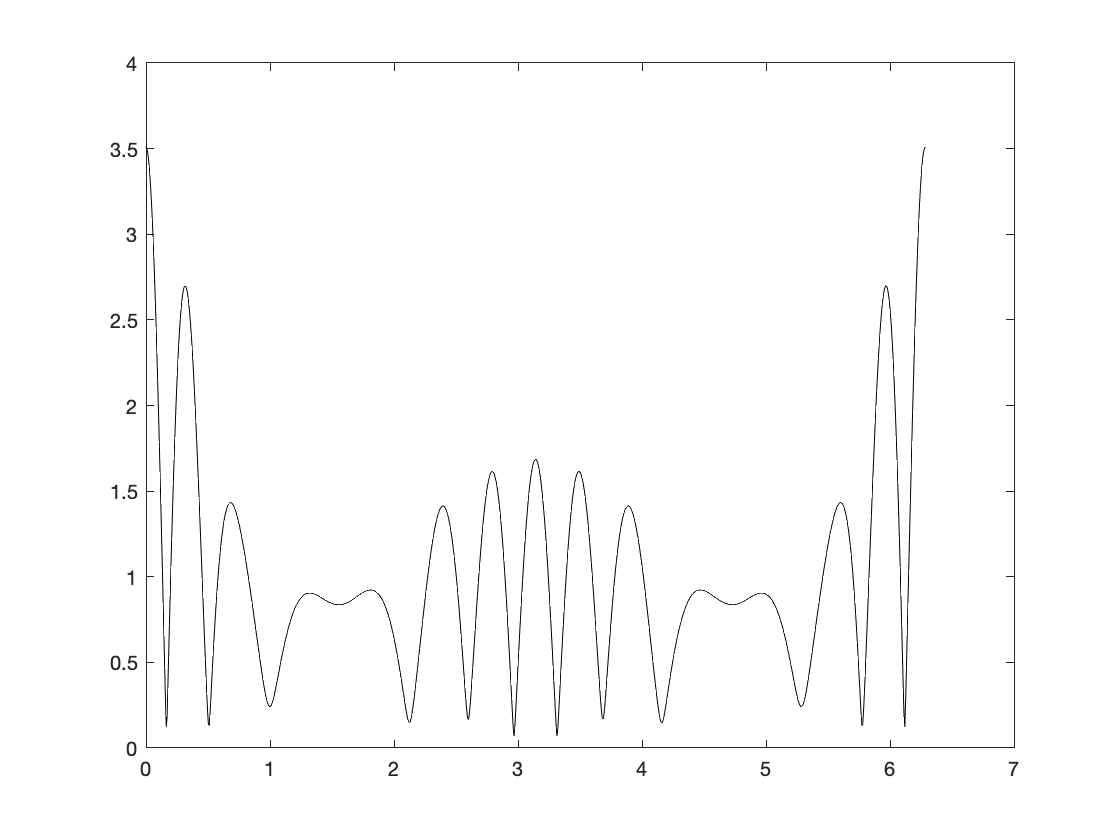

figure
plot(theta,abs(f),'k-')

Check:

% a = regularwavefunctionexpansion(n,0,uinc);
% b = mie_tmatrix(kwave,rad,n,'SOFT') * a;
% g = b.evaluateFarField(z);
% plot(theta,abs(f),'k',theta,abs(2*g),'r--')

### Computing and plotting the total field

Finally, we will plot the total field on a domain containing the two scatterers. To do this we first need to choose the domain and setup the mesh points. 

We will use a square domain $[-L,L] \times [-L,L]$ where $L = |\mathbf{x}_1 - \mathbf{x}_2|$ is the distance between the scatterers. 

L = abs(x1-x2);

We will choose the number of points $m$ in each direction of the mesh so that we have ten points per wavelength in each direction.

ppw = 10;
m = ceil(ppw*2*L/lambda);

Now create a mesh of the domain and get the points in complex-number format.

[x,y] = meshgrid(linspace(-L,L,m));
z = x + 1i * y;

Then we evaluate the total field at the mesh points using the radiating wavefunction expansions $b_1$ and $b_2$, and the incident field $u^{inc$.

u = b1.evaluate(z) + b2.evaluate(z) + uinc.evaluate(z);

The radiating wavefunction expansions are valid only outside the scatterers, so we apply a mask to the total field to ensure the field inside the scatterers is not plotted.

u(abs(z-x1) < rho | abs(z-x2) < rho) = NaN;

Finally we plot the field, and make the figure look nice.

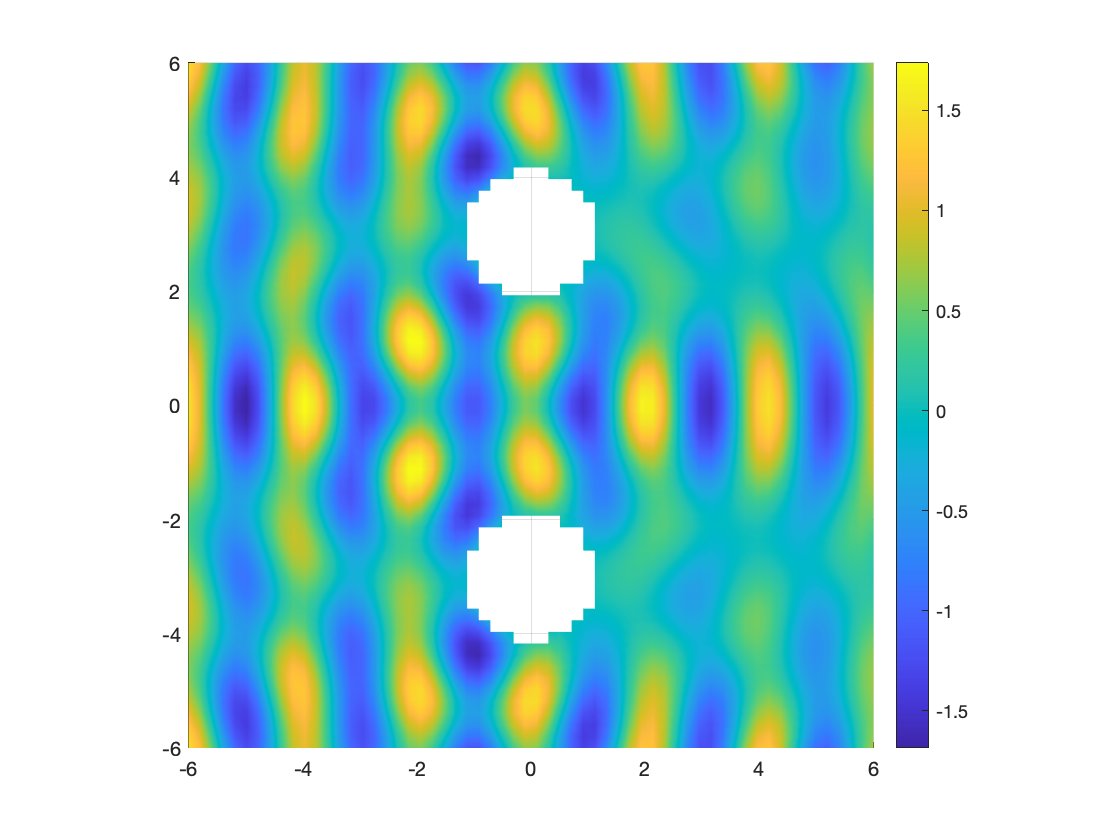

figure
surf(x,y,zeros(size(u)),real(u));
shading interp
axis equal
view([0 90])
colorbar

Define a function to do the matrix-vector product with the matrix

        $\left( \begin{array}{cc} I & - T_1 S_{12} \\ -T_2 S_{21} & I \end{array} \right)$.

function y = matrix_product(x,n,kwave,x1,x2,T1,T2)

% unpack the vector x into two radiating wavefunction expansions
c1 = radiatingwavefunctionexpansion(n,x1,kwave,x(1:2*n+1));
c2 = radiatingwavefunctionexpansion(n,x2,kwave,x(2*n+2:end));

% apply the matrix... note that the change of origin 
%     d1 = S_{12} c2
% is implemented in TMATROM using 
%     d1 = regularwavefunctionexpansion(c2,x1)
d1 = c1 - T1 * regularwavefunctionexpansion(c2,x1);
d2 = c2 - T2 * regularwavefunctionexpansion(c1,x2);

% pack the coefficients of the radiating wavefunction expansions
% back into a vector
y = [d1.coefficients;d2.coefficients];

end